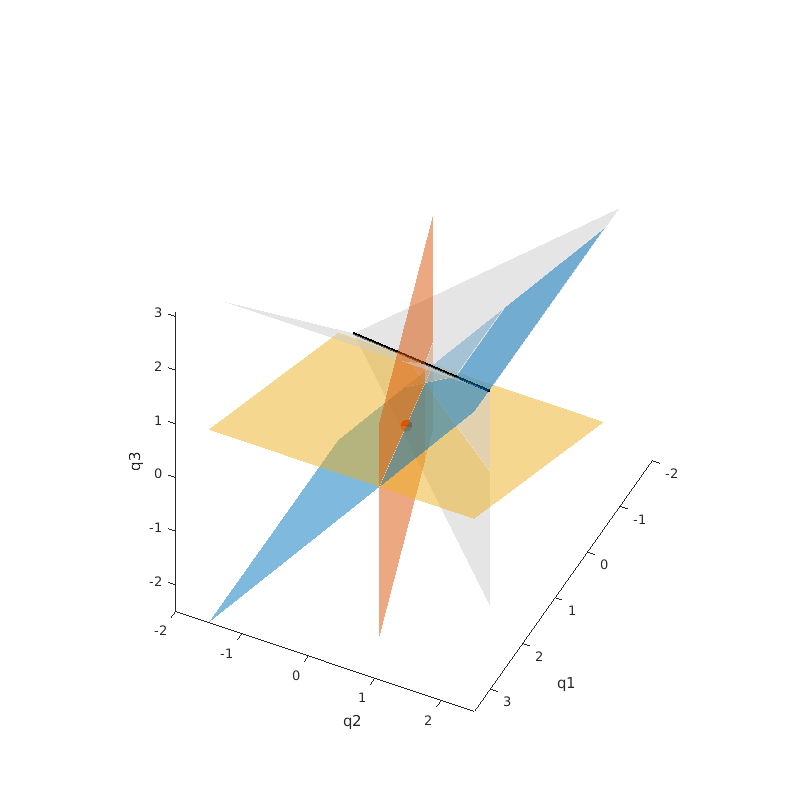

clear
clc

blue = [0 0.45 0.74] ; 
red = [0.85 0.33 0.01] ; 
yellow = [0.93 0.69 0.12] ; 
purple = [0.49 0.18 0.55] ;
green = [0.46 0.67 0.19] ;
grey = [0.8 0.8 0.8] ;
black = [0 0 0] ;

q = [1.5 0.5 0.3] ;

w1 =0.2 ;
w2 =0.7 ;
w3 =0.5 ;

lin = -2:0.01:2 ;
[X, Y] = meshgrid(lin) ;

figure("position", [0,0,800,800])
hold on

% % 1 nullclines
% surf(q(1) + X, q(2) + Y, q(3) + zeros(size(X)), "FaceColor", black, 'FaceAlpha', 0.2, "EdgeColor", "none")
% % 2 nullcline
% surf(q(1) + zeros(size(X)), q(2) + X, q(3) + Y, "FaceColor", black, 'FaceAlpha', 0.2, "EdgeColor", "none")
% % 3 nullcline
% surf(q(1) + X, q(2) + zeros(size(X)), q(3) + Y, "FaceColor", black, 'FaceAlpha', 0.2, "EdgeColor", "none")

% q-value
plot3(q(1), q(2), q(3), "." ,"MarkerSize", 30, "MarkerEdgeColor", red)

% diff 1-2
surf(q(1) + X, q(2) + w1/w2*X, q(3) + Y, "FaceColor", red, 'FaceAlpha', 0.5, "EdgeColor", "none")
% surf(X, q(2) + w1/w2*(X-q(1)), q(3) + X, "FaceColor", green, 'FaceAlpha', 0.5, "EdgeColor", "none")
% diff 1-3
surf(q(1) + X, q(2) + Y, q(3) + w1/w3*X, "FaceColor", yellow, 'FaceAlpha', 0.5, "EdgeColor", "none")
% diff 2-3
surf(q(1) + X, q(2) + Y, q(3) + w2/w3*Y, "FaceColor", blue, 'FaceAlpha', 0.5, "EdgeColor", "none")

% boundary 1-2
Z = Y ;
Z(Z>=X) = nan ;
surf(X, X, Z, "FaceColor", grey, 'FaceAlpha', 0.5, "EdgeColor", "none")
% boundary 1-3
surf(X, Z, X, "FaceColor", grey, 'FaceAlpha', 0.5, "EdgeColor", "none")
% boundary 2-3
surf(Z, X, X, "FaceColor", grey, 'FaceAlpha', 0.5, "EdgeColor", "none")
% identity
plot3(lin, lin, lin, "-" , "Color", black, "LineWidth", 2)

hold off
view(110, 40)
xlabel("q1")
ylabel("q2")
zlabel("q3")
axis equal